## 循环语句

### 5.1 目标：练习 for 循环语句

内容：计算 1 到 100 之间所有奇数的和。

sum = 0; % Initialization parameter

for i = 1:2:100
sum = sum +i;
end
sum

sum = 2500

### 5.2 目标：练习 for 循环语句

1.从脚本 tallBuildingRecord_template开始：

2.修改脚本，使用循环找出每一年的最高建筑。

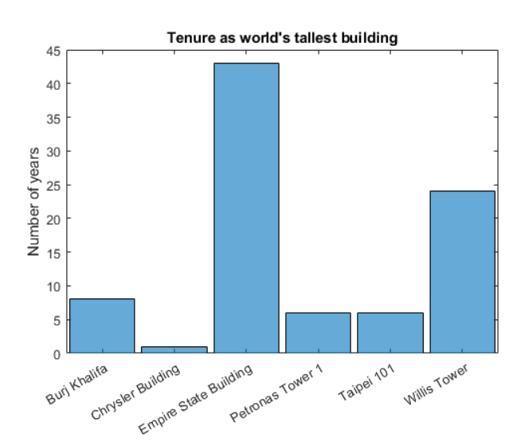

edit tallBuildingRecord_template.mlx 
edit tallBuildingRecord.mlx 

### 5.3 目标：练习嵌套 for 循环语句

步骤 1：在区间 [1,5] 内随机生成一个 3 行 5 列的整数矩阵 A；

步骤 2：在区间 [1,5] 内随机生成一个 5 行 2 列的整数矩阵 B；

步骤 3：用嵌套 for 循环计算矩阵 A*B**，得到结果 **C**；*

*步骤 4**：直接计算矩阵 **D = A*B。

### 5.4 目标：练习 while 循环语句

内容：从键盘输入若干个数，当输入 0 时结束，求这些数的平均值及其总和。

msum=0;        % 初始化总和变量为 0
n=0;           % 初始化数字个数计数器为 0
x=input('Enter a number (end in 0):');  % 提示用户输入第一个数字

while x~=0     % 当输入的数字不等于 0 时循环
    msum=msum+x;  % 将输入的数字累加到总和中
    n=n+1;        % 数字个数加 1
    x=input('Enter a number (end in 0):');  % 继续获取下一个数字输入
end 

if n>0        % 如果至少输入了一个非零数字
    fprintf('sum=%f\n',msum);     % 输出总和
    mean=msum/n;                  % 计算平均值
    fprintf('mean=%f\n',mean);    % 输出平均值
end

### 5.5 目标：练习向量循环与计时

步骤 1：令 i 为 1 到 10^7 的自然数，用 for 循环计算 A(i) = sin(i)*cos(i)，并记录 for 循环的运行时间；

步骤 2：用矩阵方法实现 A(i) = sin(i)*cos(i)，并记录计算时间。

clear
% with for loop
tic
for i = 1 : 10^7
A = sin(i) * cos(i);
end
t1 = toc
% with matrix method
B = zeros(1, 10^7);
tic
j = 1 : 10^7
B(1,j) =sin(j) .* cos(j);
t2 = toc